# Illustration of the beam geometry

This script explore the various beam geometry effect and make figures to illustrates various aspect of the geometrical challenges of the 3D remapping

Load wsrlib and the functions of the package.

addpath('/Users/raphael/Documents/GitHub/wsrlib');
wsrlib_setup();
addpath(genpath('functions/'))

Select any beam with a normal beam geomtry

scans_filepath = load_rd("KBYX", datetime("19-Apr-2019 01:00"));

rd = read_rd(scans_filepath, 'maxAlt', 2000);

Starting parallel pool (parpool) using the 'Processes' profile ...



warning off

## Beam geometry

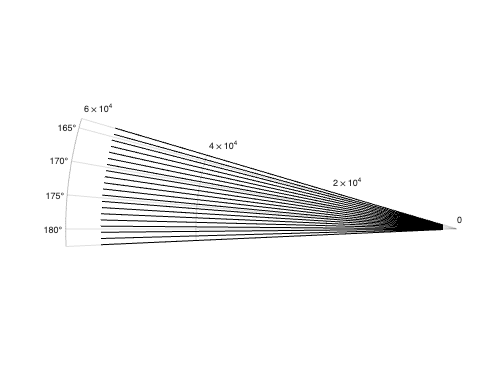

sweep = rd{1}.dens.sweeps(i_elev);
[az, range] = get_az_range(sweep);
[s, z] = slant2ground(range, sweep.elev);
az=az(1:20);
range= range(z<4000);

figure; 
polarplot(deg2rad([az az])',repmat([range(1) range(end)],numel(az),1)','k')
thetalim(([az(1) az(end)]));

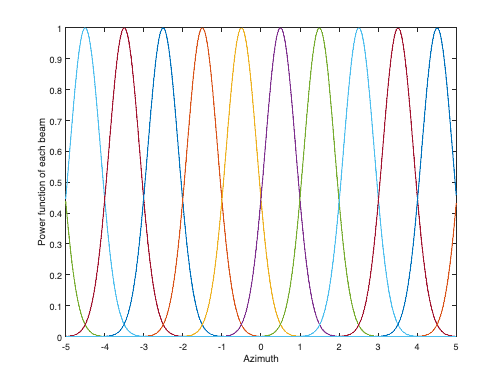

x_az=-5:.001:5;
hpbw = 0.925; % half power beamwiths
s=hpbw/2/sqrt(2*log(2));
w_az=exp(- (x_az-(az-mean(az))).^2 / (2*s^2) );
figure; plot(x_az, w_az);
xlabel("Azimuth"); ylabel("Power function of each beam")

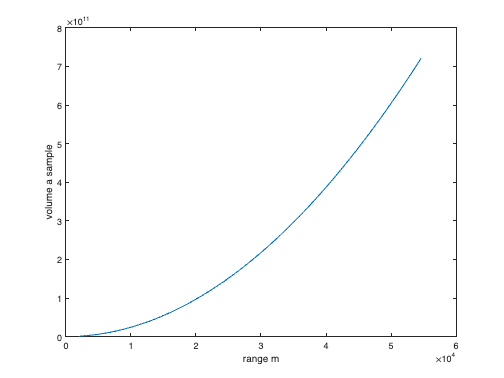

figure; plot(range, pi* (range * tan(diff(az(1:2))/2)).^2 * 250);
xlabel('range m'); ylabel('volume a sample')

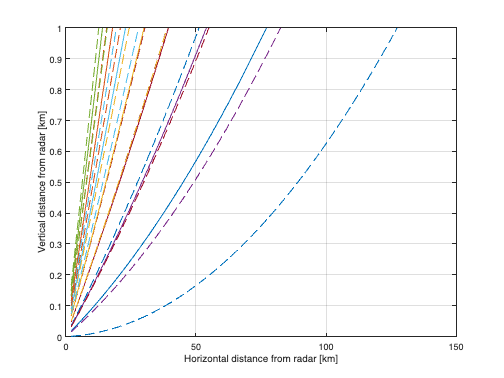

figure; hold on;
for i_elev=1:numel(rd{1}.dens.sweeps)
    sweep = rd{1}.dens.sweeps(i_elev);
    [~, range] = get_az_range(sweep);
    [s, z] = slant2ground(range, sweep.elev);
    p=plot(s/1000, z/1000);
    [s, z] = slant2ground(range, sweep.elev-hpbw/2); plot(s/1000,z/1000,'--',Color=p.Color)
    [s, z] = slant2ground(range, sweep.elev+hpbw/2); plot(s/1000,z/1000,'--',Color=p.Color)
end
xlim([0 150]); ylim([0 1]);
xlabel('Horizontal distance from radar [km]')
ylabel('Vertical distance from radar [km]')
box on; grid on; %axis equal tight;

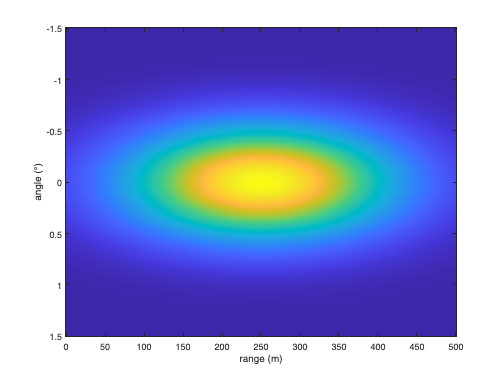

simga_tp=hpbw/2/sqrt(2*log(2));
simga_r = 0.35*median(diff(range));
s=0.5;
p=(-3*s):.01:(3*s);
t=p;
r=0:1:500;
r0=250;
p0=0;t0=0;

[RR,PP,TT]=meshgrid(r,p,t);
f = exp(-(RR-r0).^2/4/simga_r^2) .* exp(-(TT-t0).^2/2/simga_tp^2 - (PP-p0).^2/2/simga_tp^2 );

figure; imagesc(r,t,f(:,:,round(end/2)))
xlabel('range (m)'); ylabel('angle (°)')

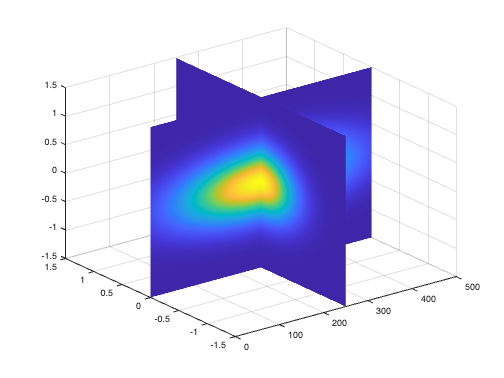

figure; c=slice(RR,PP,TT,f,[250],[0],[]);
set(c,"EdgeColor","none");

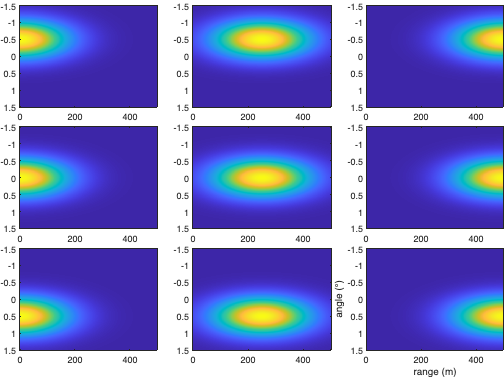

figure; tiledlayout('flow','TileSpacing','tight','Padding','tight')
for i_t=[-.5 0 .5]
    for i_r=[-250 0 250]
        f2 = exp(-(RR-(r0+i_r)).^2/4/simga_r^2) .* exp(-(TT-(t0)).^2/2/simga_tp^2 - (PP-(p0+i_t)).^2/2/simga_tp^2 );
        nexttile; imagesc(r,t,f2(:,:,round(end/2)))
    end
end
xlabel('range (m)'); ylabel('angle (°)')

## Scans geometry

r_lim = 50000;
gridsize = num2str(r_lim/1000)+"km";
[df, rd] = load_F_elev("data/" + gridsize + "/", rd);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).


g = create_grid(df, rd);
[gX,gY,~]=meshgrid(g.x,g.y,g.z);
[gLON,gLAT,gZ]=meshgrid(g.lon,g.lat,g.z);
[F, ~, info] = construct_F(rd, df, g);
szf = size(F);

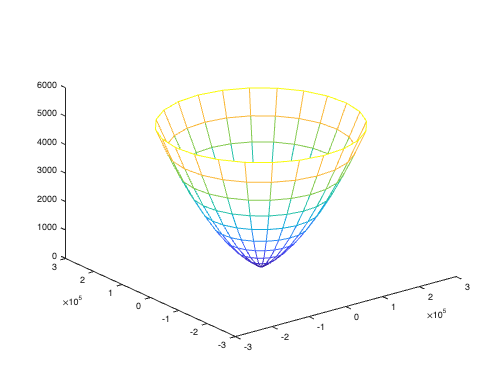

sweep = rd{1}.dens.sweeps(1);
[az, range] = get_az_range(sweep);
az = cmp2pol(az);
[s, z] = slant2ground(range, sweep.elev);
% reduce size for graphical
rn=10;daz=30;
max_z=5000; id_max_z = find(max_z<z,1);
min_r=5000; id_min_r = find(min_r<range,1);
id_rz = unique(round(linspace(id_min_r,id_max_z, rn)));
[az, range, z] = expand_coords([az(1:daz:end); az(1)], range(id_rz), z(id_rz));
[x,y,z] = pol2cart(az,range,z);
figure; hold on; mesh(x,y,z); view(3)

## Figure of radars scan

Load DEM

load('../BMM-US/data/density/inference-trans.mat','radar');
load('../BMM-US/data/DEM/dem');
% dem(dem==-9999)=nan;
dl=10;
dem_lon = dem_lon(1:dl:end);
dem_lat = dem_lat(1:dl:end);
dem = dem(1:dl:end,1:dl:end);
earth_radius = 6371200; 
a_xis = [-125 -67 24.5 50];

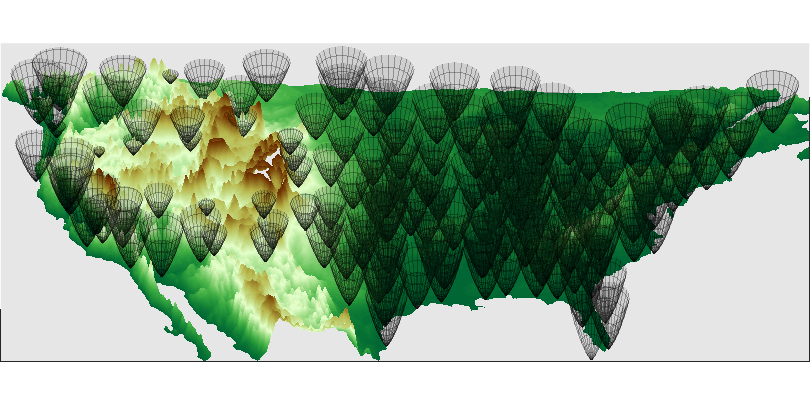

figure(Position=[0 0 900 450]);  tiledlayout('flow','TileSpacing','tight','Padding','tight'); nexttile;hold on;
surf(dem_lon,dem_lat,imgaussfilt(dem,1),'EdgeColor','none',"FaceColor","interp")
demcmap([0 3000]);
ax=gca; ax.DataAspectRatio = [1 1 111000/500*2]; % legend('~1:100 aspect ratio')
for i_r=1:height(radar)
    yn  = radar.lat(i_r)  + (y / 6371200) * (180 / pi);
    xn = radar.lon(i_r) + (x / 6371200) * (180 / pi) / cos(radar.lat(i_r) * pi/180);
    mesh(xn,yn,z+radar.height(i_r),'EdgeColor','k','facealpha',0.1, "FaceColor","k",EdgeAlpha=0.3);
end
yticks('')
xticks('')
zticks('')
axis([-127 -65 24.5 50 0 3000]);
ax.Color=[230 230 230]/255;
view([0 53])

% exportgraphics(gcf,'coverage_radar_3d.png','BackgroundColor',[50 50 50]/255)

## Figure of elevation coverage

M = Inf(size(dem));
[DEM_LON,DEM_LAT] = meshgrid(dem_lon,dem_lat);
for i_r=1:height(radar)
    yn  = radar.lat(i_r)  + (y / 6371200) * (180 / pi);
    xn = radar.lon(i_r) + (x / 6371200) * (180 / pi) / cos(radar.lat(i_r) * pi/180);
    vq = griddata(xn,yn,z+radar.height(i_r),DEM_LON,DEM_LAT,'cubic');
    M = min(M,vq);
end

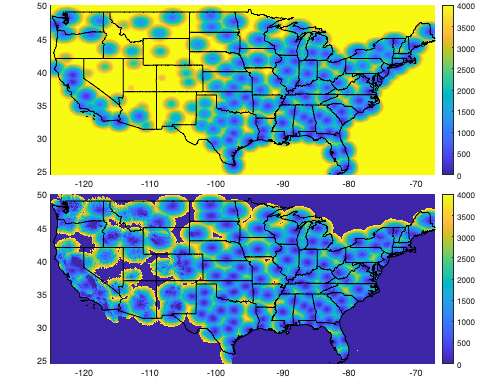

%M(M>5000)=nan;
figure; tiledlayout('flow','TileSpacing','tight','Padding','tight')
nexttile; hold on;
imagesc(dem_lon,dem_lat,M)
axis equal; axis(a_xis); clim([0 4000])
borders('states','k');colorbar;
nexttile; hold on;
M_agl = M-double(dem); M_agl(M_agl>4000)=nan;
imagesc(dem_lon,dem_lat,M_agl)
axis equal; axis(a_xis); clim([0 4000])
borders('states','k');colorbar;

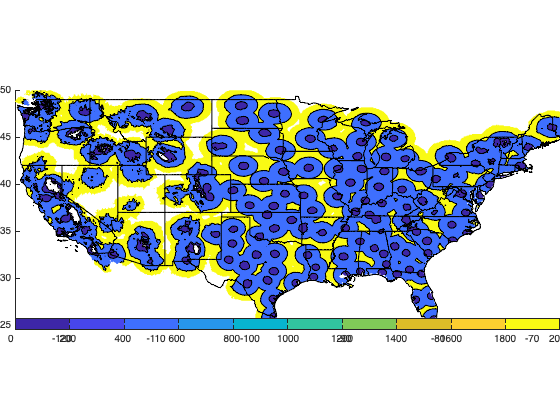


%
figure;tiledlayout('flow','TileSpacing','tight','Padding','tight')
nexttile; hold on;
l=[0 500 2000];
% c=parula; colormap(c(round(((l-min(l))/(max(l)-min(l))*(height(c)-1)))+1,:));
contourf(dem_lon,dem_lat,M_agl,l)
axis equal; axis(a_xis);
borders('states','k');%colorbar;
contourcmap('parula','Colorbar','on','Location','horizontal')

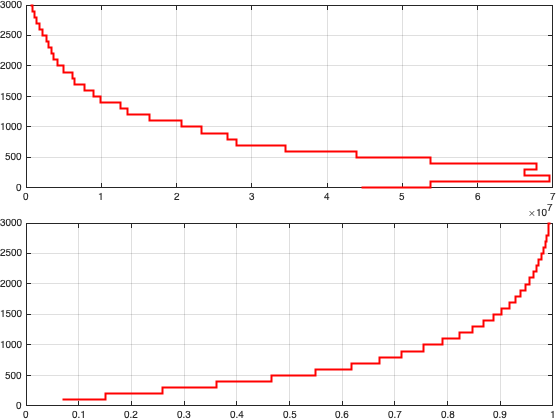

% Average taken for a single radar
sumDens=[44513475.891 53680048.982 69508973.873 66213010.691 67817613.191 53768139.273 43907005.382 34454054.573 27900100.355 26768740.700 23289734.855 20696603.009 16365323.927 13492206.200 12529782.173  9913382.673  8918249.809  7803051.682  6506475.818  6146458.264  4973314.400  4161616.327  3598211.882  3405080.927  3034654.009  2674818.755  2199888.964  1777663.600  1447718.636  1073300.936   886175.291   763461.618   674415.255   539293.336   438944.027   368327.700   309427.373   267850.036   218005.682   177035.573   130663.545    90338.700    66038.264    43867.609    30847.745    22109.009    14719.218    12554.736     8475.918     5412.264];
heightSumDens=0:100:4900;

figure; tiledlayout('flow','TileSpacing','tight','Padding','tight'); 
nexttile;stairs(sumDens,heightSumDens,'r','linewidth',2); ylim([0 3000]); grid on;
nexttile;stairs(cumsum(sumDens)/sum(sumDens),(heightSumDens)+100,'r','linewidth',2); ylim([0 3000]); xlim([0 1]); grid on;

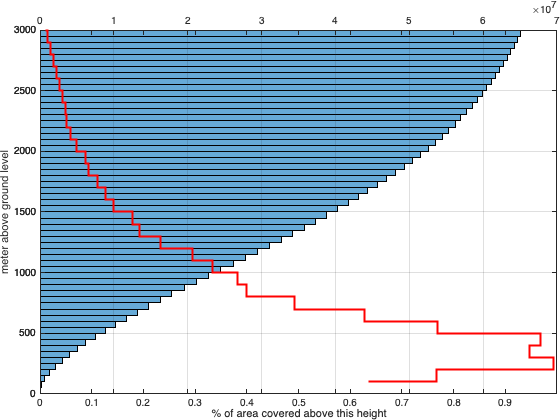

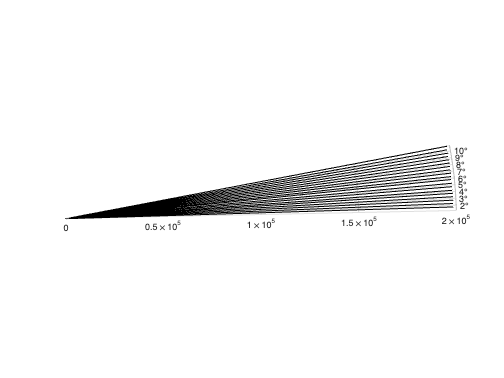

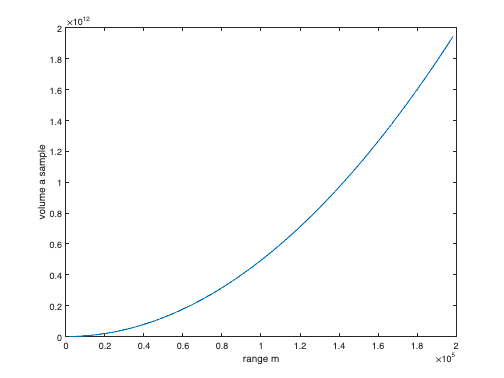

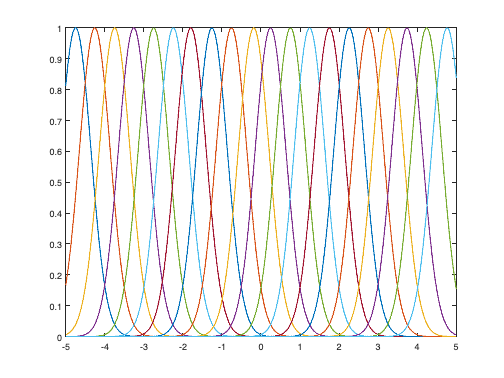

Dot indexing is not supported for variables of this type.

figure;t=tiledlayout('flow','TileSpacing','tight','Padding','tight'); ax1 = axes(t);
tmp=M_agl(:,dem_lon>-103);tmp=tmp(~isnan(tmp));
histogram(ax1,tmp,'Normalization','cdf', 'Orientation', 'horizontal'); axis tight;ylim(ax1,[0 3000]);
ylabel(ax1,'meter above ground level'); xlabel(ax1,'% of area covered above this height')
ax2 = axes(t); 
stairs(ax2,sumDens,(heightSumDens)+100,'r','linewidth',2)
ax2.XAxisLocation = 'top'; ax2.Color = 'none';
ax2.Box = 'off';

ylim(ax2,[0 3000]); grid on; box on